# Stationary Iterative Methods for Linear Systems

This is a typical problem for linear solvers. discretize Poisson's equation in 2-D


$$-\Delta u=-\left(\frac{\partial^2 }{\partial x^2 }u+\frac{\partial^2 }{\partial y^2 }u\right)=f$$


on a square grid using centered �finite difference approximations


$$4u_{\textrm{ij}} -u_{i-1,j} -u_{i+1,j} -u_{i,j-1} -u_{i,j+1} =h^2 f_{\textrm{ij}} \ldotp$$


- Dirichlet conditions $u = 0$ on boundaries

- Grid spacing $h = 1/(n + 1)$

- Total $n^2$ unknowns $u_{ij}$

We will discretize on a $(n+2)\times(n+2)$ rectangular grid, and the unknowns will be the values on the unknown function on the inner grid points.  We need also to choose a consistent ordering for the unknonws (e.g.upward, left to right).

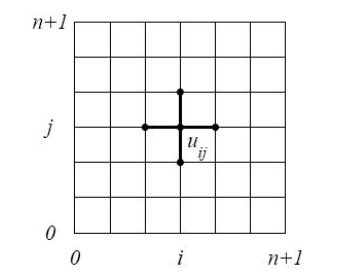

The system matrix ($n^2\times n^2$) has the following block symmetric tridiagonal form


$$A=\left\lbrack \begin{array}{ccccc}
X & I & O & \cdots  & O\\
I & X & I & \ddots  & \vdots \\
O & I & X & \ddots  & O\\
\vdots  & \ddots  & \ddots  & \ddots  & I\\
O & \cdots  & O & I & X
\end{array}\right\rbrack ,\textrm{where}\;X=\left\lbrack \begin{array}{ccccc}
-4 & 1 & 0 & \cdots  & 0\\
1 & -4 & \ddots  & \ddots  & \vdots \\
0 & \ddots  & \ddots  & 1 & 0\\
\vdots  & \ddots  & 1 & -4 & 1\\
0 & \cdots  & 0 & 1 & -4
\end{array}\right\rbrack \ldotp$$


$X$ is $n\times n$, $I$ is the $n\times n$ unit matrix and $O$ is the $n\times n$ null matrix.

f=@(x,y) 5*pi^2*sin(pi*x).*sin(2*pi*y);
n=100;

Construct matrix 

h=1/(n+1); e=ones(n,1);
A1=spdiags([-e,2*e,-e],-1:1,n,n);
I=speye(n,n);
A=kron(A1,I) + kron(I,A1);

or simply

x=linspace(0,1,n+2); y=x;
[X,Y]=meshgrid(x(2:end-1));
b=h^ 2*f(X,Y);
b=b(:);
[X,Y]=meshgrid(x);

The resulting linear system $Au = b$ is sparse and banded

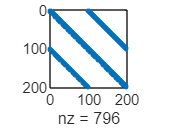

spy(A(1:200,1:200))

- $A$ is symmetric positive defi�nite, with eigenvalues $ \lambda_{ij} = \lambda_i + \lambda_j $, $i , j = 1, \dots , n$, where $\lambda_k =2\left(1-\frac{\cos \pi k}{n+1}\right)$ are eigenvalues of the 1-D Laplace operator

- Largest eigenvalue $\lambda_n =2\left(1-\frac{\cos \pi n}{n+1}\right)\approx 4$

- Smallest eigenvalue $\lambda_1 =2\left(1-\cos \frac{\pi }{n+1}\right)\approx \frac{\pi^2 }{{\left(n+1\right)}^2 }$

- Condition number $\textrm{cond}\left(A\right)=\frac{\lambda_n }{\lambda_1 }\approx \frac{4{\left(n+1\right)}^2 }{\pi^2 }$

Solve the system with Jacobi

[s1,ni1]=Jacobi(A,b, zeros(n^2,1),1e-8,n^2);
ni1

ni1 = 9675

s1

s1 =     0.0019
    0.0039
    0.0058
    0.0077
    0.0095
    0.0113
    0.0131
    0.0149
    0.0165
    0.0181


For  our problem, the splitting is $A = D - L -U = 4I - (4I - A)$ and the Jacobi matrix is $T_J = (4I )^{-1}(4I - A) = I - A/4$, with eigenvalues $1-\frac{\lambda_{ij}}{4}$. The spectral radius is 


$$\rho \left(T_J \right)=\max_{\textrm{ij}} \left|1-\frac{\lambda_{\textrm{ij}} }{4}\right|=\left|1-\frac{\lambda_{11} }{4}\right|=\cos \frac{\pi }{n+1}\approx 1-\frac{\pi^2 }{2{\left(n+1\right)}^2 }<1\ldotp$$


Therefore, it converges with a constant factor every $O(n^2)$ iteration.

rho_Jacobi=1-pi^2/2/(n+1)^2

rho_Jacobi = 0.9995

Gauss-Seidel method

[s2,ni2]=Gauss_Seidel(A,b, zeros(n^2,1),1e-8,n^2);
ni2

ni2 = 7921

SOR method: the optimal $\omega$ is $\omega=2\left(1+sin \frac{\pi}{n+1}\right)$ and the spectral radius is 


$$\rho \left(T_{\omega } \right)\approx 1-\frac{2\pi }{n+1}\ldotp$$


w=2*(1-(2*pi)/(n+1))

w = 1.8756

[s3,ni3]=relax(A,b, w, zeros(n^2,1),1e-8,n^2);
ni3

ni3 = 863

Finally, we build the solution and plot it

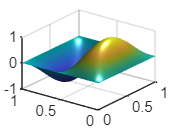

[X,Y]=meshgrid(x);
U=zeros(n+2);
U(2:end-1,2:end-1)=reshape(s3,n,n);
surf(X,Y,U)
shading interp
camlight
view([-53.31 33.28])